% Just working through model-free RL for our Simulink environment

% Setting up environment

% NEED TO INCORPORATE CO-ORDINATE TRANSFORM IN SIMULINK; CURRENTLY JUST
% TAKING THE WHOLE STATE VECTOR AS CONCATENATED IN SIMULINK 

open_system("pendulum_system_RL_model_free")
obsInfo = rlNumericSpec([8 1])

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [8 1]
       DataType: "double"


obsInfo.Name = "Robot States";
%obsInfo.Description = "phi, r, theta, dphi, dr, dtheta";
obsInfo.Description = "phi, r, theta, dphi, dr, dtheta, something, something_else";

actInfo = rlNumericSpec(1);
actInfo.Name = "Motor Torque";
actInfo.LowerLimit = -0.02;
actInfo.UpperLimit = 0.02;

envModelFree = rlSimulinkEnv("pendulum_system_RL_model_free", ...
    "pendulum_system_RL_model_free/RL Agent", ...
    obsInfo,actInfo);

% NEED TO CREATE A RESET FUNCTION TO RANDOMLY INITIALISE THE STARTING ANGLE
% OF THE PENDULUM

envModelFree.ResetFcn = @(in)localResetFcn(in);
Ts = 0.1;
Tf = 2000;
rng(0)


% Setting up critic (DDPG)
statePath = [
    featureInputLayer(obsInfo.Dimension(1),Name="netObsIn")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(25,Name="CriticStateFC2")];

actionPath = [
    featureInputLayer(actInfo.Dimension(1),Name="netActIn")
    fullyConnectedLayer(25,Name="CriticActionFC1")];

commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "CriticStateFC2", ...
    "add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "CriticActionFC1", ...
    "add/in2");

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 1.8k

   Inputs:
      1   'netObsIn'   8 features
      2   'netActIn'   1 features



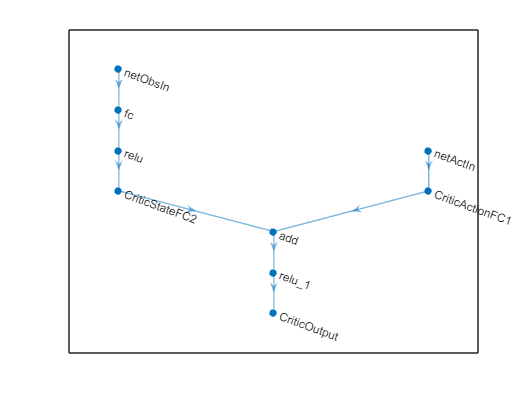

% Displaying critic
figure
plot(criticNetwork)

% Creating critic approximator
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo, ...
    ObservationInputNames="netObsIn", ...
    ActionInputNames="netActIn");

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
0.0239

% Creating the actor
actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];
actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 31

   Inputs:
      1   'input'   8 features



actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.9158]}


% Creating the agent

agentModelFreeRL = rlDDPGAgent(actor,critic);
agentModelFreeRL.SampleTime = Ts;

agentModelFreeRL.AgentOptions.TargetSmoothFactor = 1e-3;
agentModelFreeRL.AgentOptions.DiscountFactor = 1.0;
agentModelFreeRL.AgentOptions.MiniBatchSize = 64;
agentModelFreeRL.AgentOptions.ExperienceBufferLength = 1e6; 

agentModelFreeRL.AgentOptions.NoiseOptions.Variance = 0.3;
agentModelFreeRL.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agentModelFreeRL.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agentModelFreeRL.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agentModelFreeRL.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agentModelFreeRL.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
getAction(agentModelFreeRL,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.0200]}


% Training agent

% NEED TO CREATE A BETTER REWARD FUNCTION AND AN ISDONE FUNCTION THAT
% ALLOWS THE SIMULATION TO RUN LONG ENOUGH TO EXPLORE THE ENTIRE STATE
% SPACE

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=800);

trainingStats = train(agentModelFreeRL,envModelFree,trainOpts);

% Simulate environment
simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="off");
experiences = sim(envModelFree,agentModelFreeRL,simOpts);
